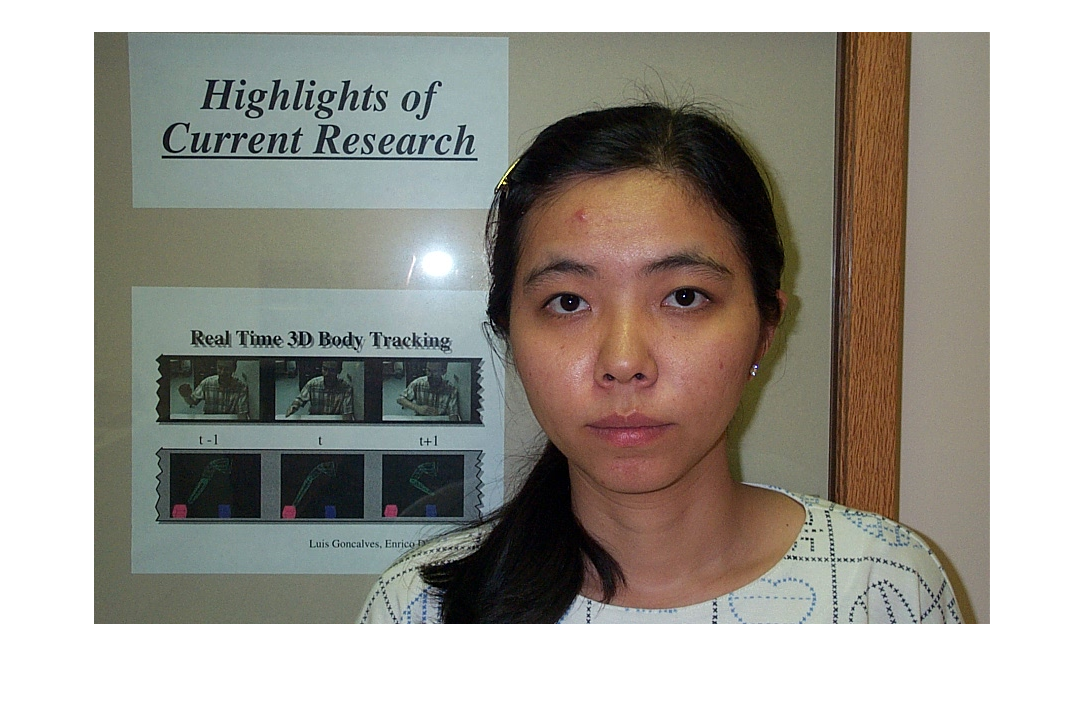

image = (imread("../DB2/il_16.jpg"));
imshow(image);

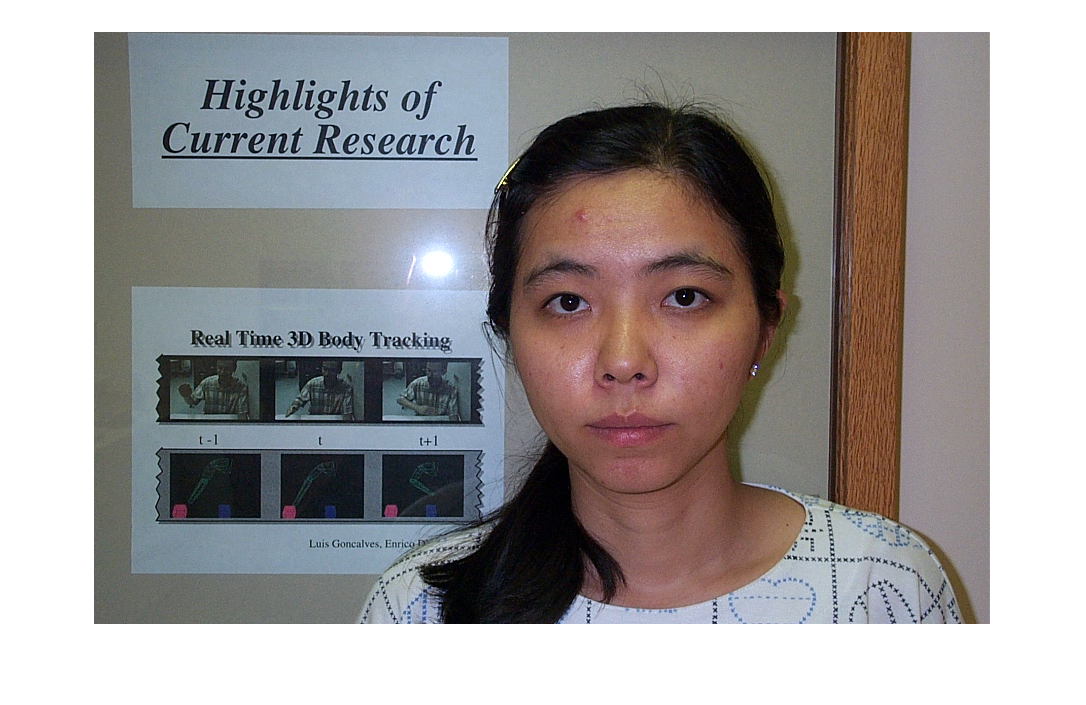

image = colorCorrection(image);
facemask = generateFaceMask(image);
imshow(image);

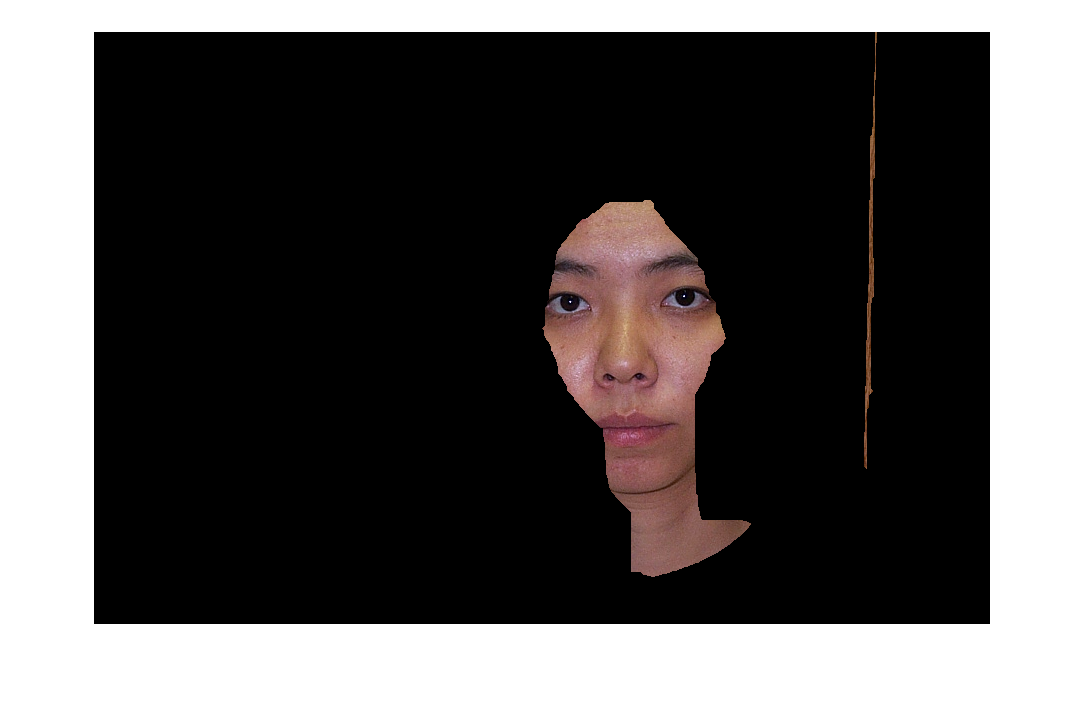

image = im2double(image);
imshow(facemask .* image);

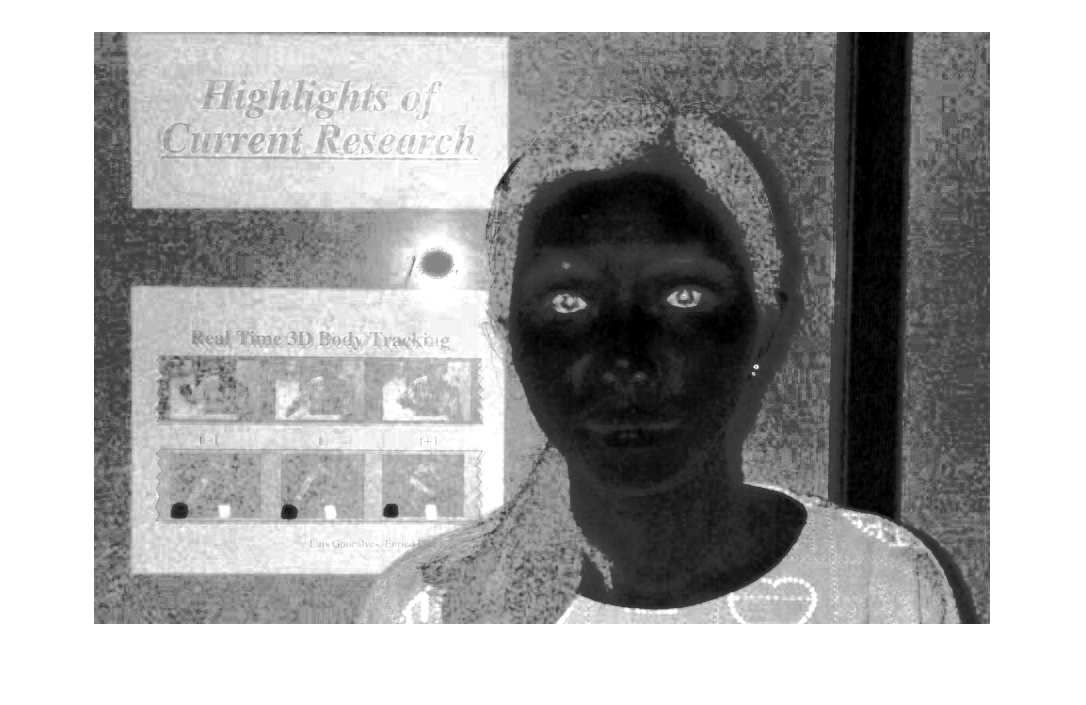

%transform to YCbCr color space 
chroma_img = rgb2ycbcr(image);

Y = chroma_img(:,:,1);
Cb = chroma_img(:,:,2);
Cr = chroma_img(:,:,3);
Cr_c = 1 - Cr; %complement of Cr

cbcb = Cb .* Cb;
crcr_c = Cr_c .* Cr_c;
cbcr = Cb./Cr;

%Normalize values between 0 and 1
cbcb = normalizeimg(cbcb);
crcr_c = normalizeimg(crcr_c);
cbcr = normalizeimg(cbcr);

eyemapc = 1/3 .* (cbcb + crcr_c + cbcr);
%imshow(eyemapc);
%imshow(histeq(eyemapc));
%histogram equalize to pop eyes better
eyemapc = histeq(eyemapc);
imshow(eyemapc);

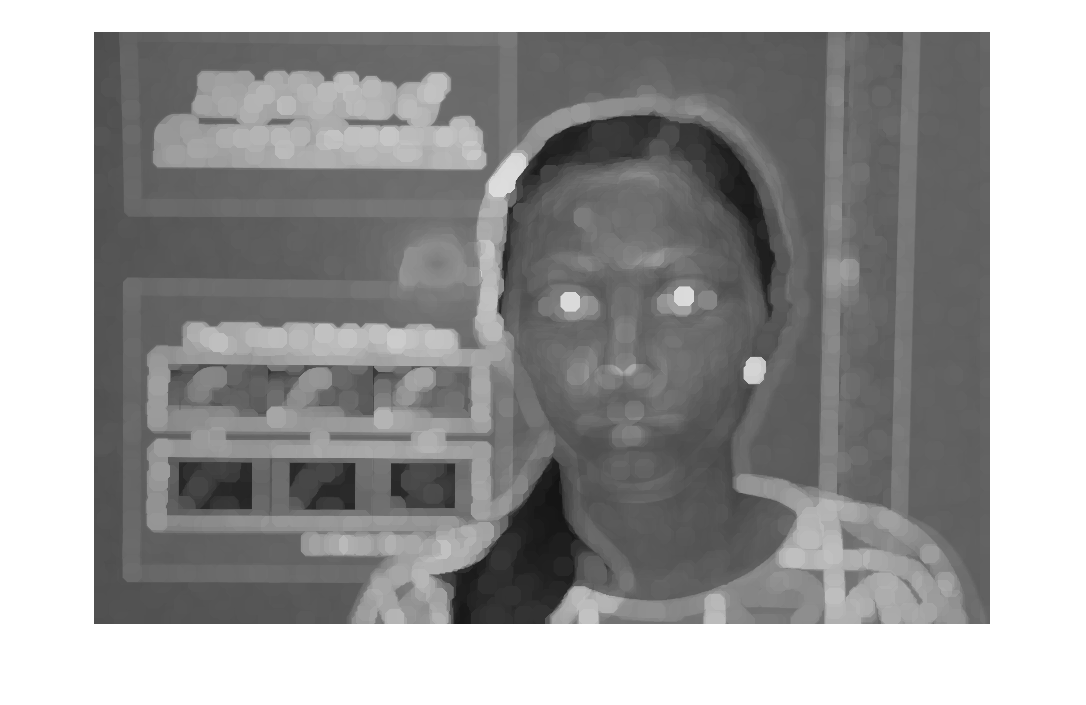

%im1 = histeq(eyemapc);

se = strel('disk', 10);
eyemapl = imdilate(Y, se) ./ (imerode(Y, se) + 1);

imshow(eyemapl)

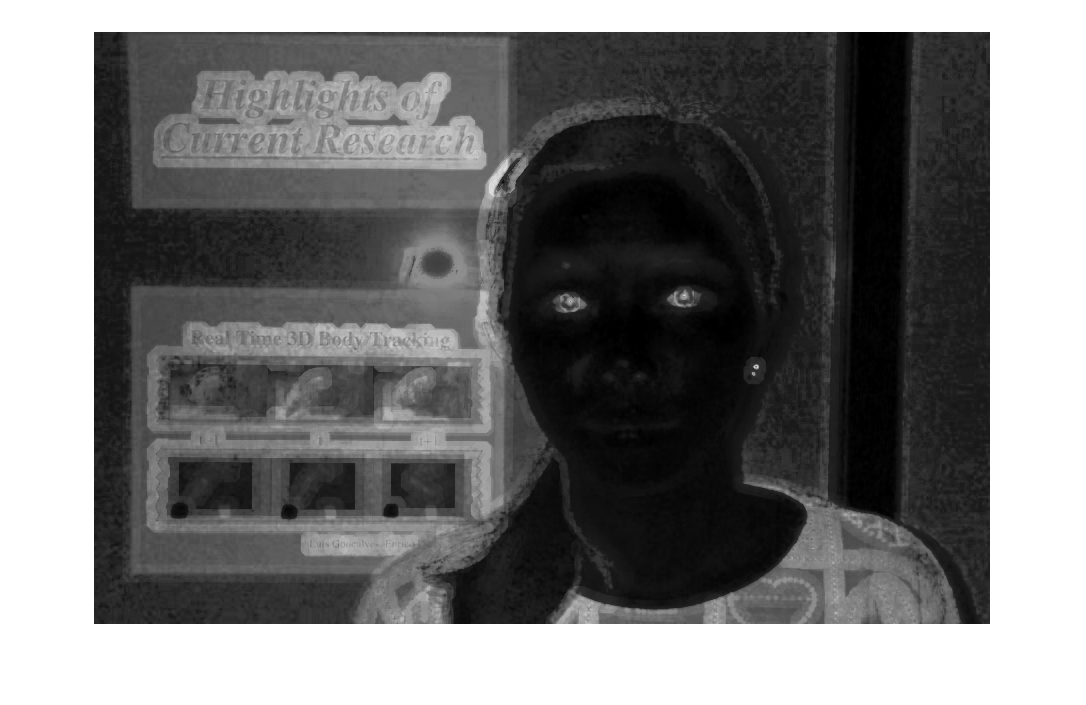


eyemap = eyemapc .* eyemapl;
imshow(eyemap);

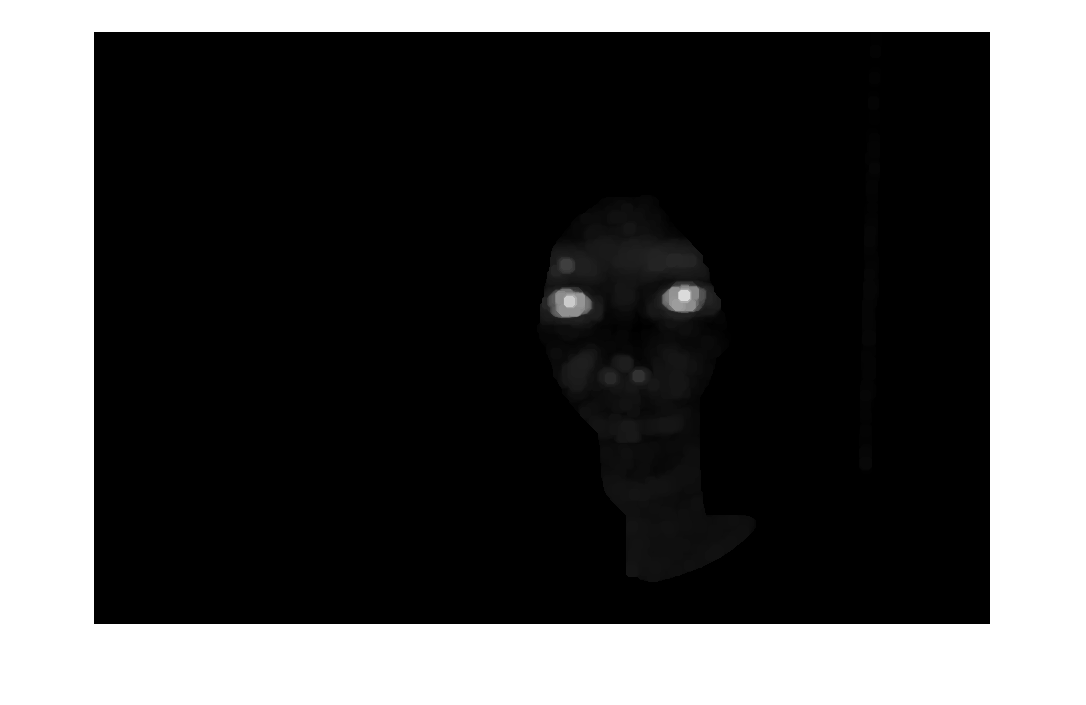

eyemap = eyemap .* facemask;
se = strel('disk', 6);
eyemap = imdilate(eyemap, se);
imshow(eyemap);

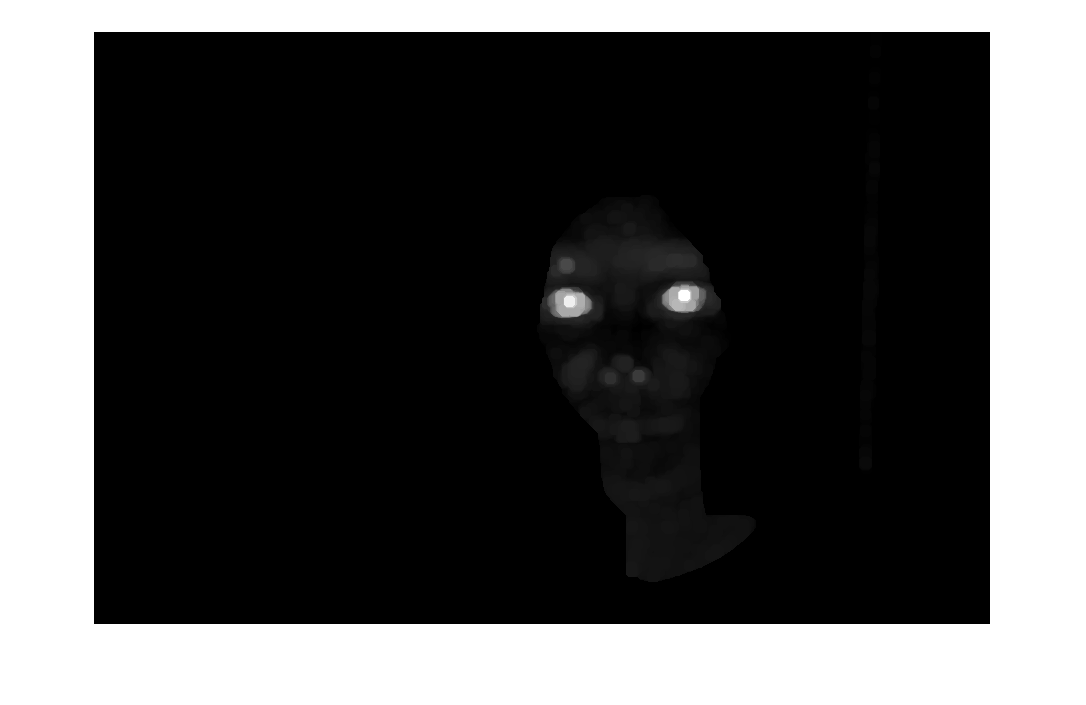

%perhaps should normalize img after dilation
eyemap = normalizeimg(eyemap);

imshow(eyemap);

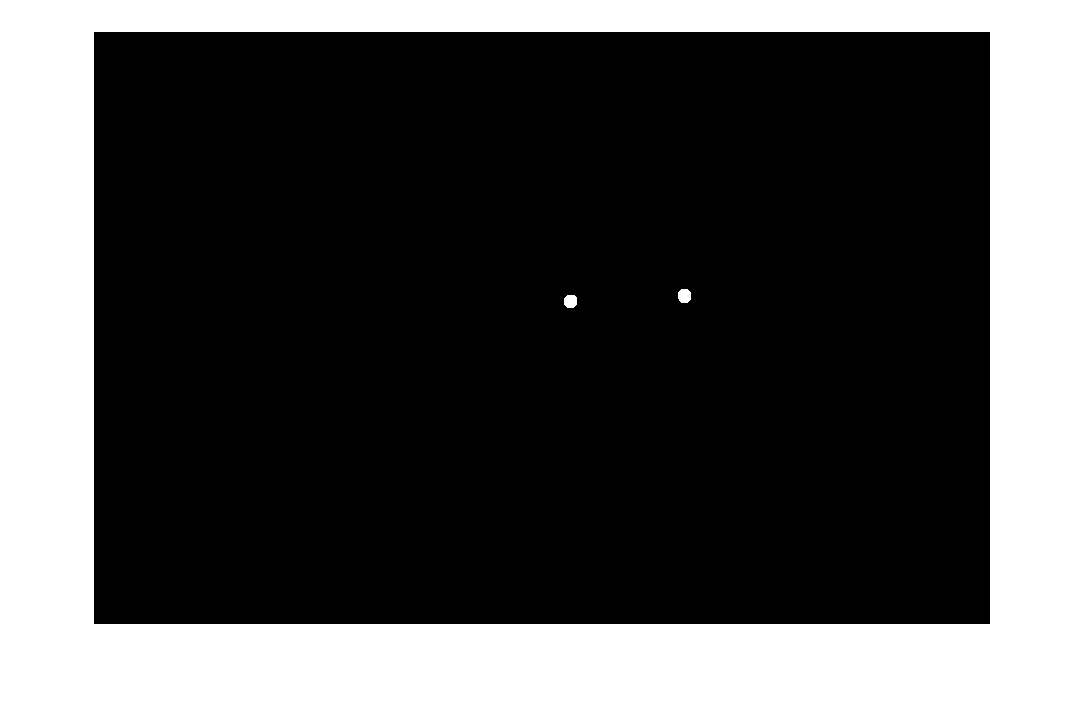


%imshow(eyemap > 0.8)

%threshold eyemap and use facemask to remove false candidates
imbinary = eyemap > 0.75; %0.7 works fairly well
imshow(imbinary)

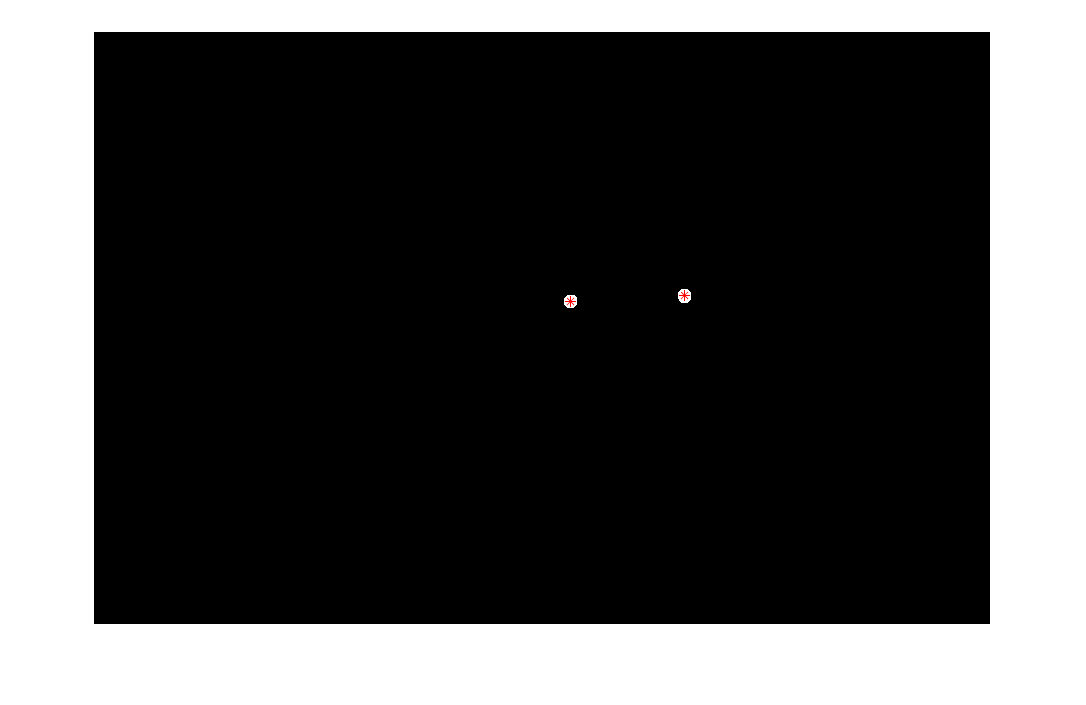


se = strel('disk', 3);
%close small gaps between objects, 
%useful for ex. when eyebrows are misstaken as eye candidates
imbinary = imclose(imbinary, se);

imshow(imbinary);

stats = regionprops(imbinary, "centroid");

%concatinate all centroids found in the image 
centroid = cat(1, stats.Centroid);
%draw centroid ontop of img
hold on
plot(centroid(:,1), centroid(:,2), "r*");



%If we have more than 2 eye candidates go through all pairs
%and compare their y-value difference, the pair of points with
%lowest y-diff are more probable to be the true candidates for the eyes
if(length(centroid) > 2) 
    eyepoints = zeros(2);
    minY = realmax;
    for i = 1:length(centroid)
        for j = i+1:length(centroid)
            y1 = centroid(i,2);
            y2 = centroid(j,2);
            heightdiff = abs(y1 - y2);
            
            if(heightdiff < minY)
                eyepoints(1,:) = centroid(i,:);
                eyepoints(2,:) = centroid(j,:);
                minY = heightdiff;
                %This can be improved further by checking the distance of the pair
                % of points to the middle in y-direction, the closer to the middle
                % the better and probably more accurate that those are the eyes
            end
        end
    end
    plot(eyepoints(:,1), eyepoints(:,2), "bo");
else
    %found 2 or less eye candidates use the given candidates as eye points
end


